## Network Model 

- You may work on a more complex network implementation, but for this milestone, the minimum requirement is that you have a network representation and simulate the progress of an infection.

- Possible network representation: Use a symmetric logical matrix to represent the contacts among people. In your final project, you may explore the dynamic nature of this network (ie., individuals self-quarantine when they are infected, exposed, and/or based on public policy). For this milestone, you may use a static network that does not change throughout the simulation. You may generate a random network or hard-code an example network.

- Use a vector to represent the starting state of each individual. You may come up with a numerical encoding (e.g., 0 to represent Susceptible, 1 to represent infected, etc.) or use a character-encoding (e.g., 'S', 'I') for the state of each individual. The minimum requirement for this milestone is to represent Susceptible and Infected.

- Using a for loop, simulate the system over many days.

- In each day:

- Consider the individuals who are in contact. Let the Infected individuals turn the Susceptible individuals they are in contact with, with a certain a probability (use similar parameters as the well-mixed SEIR model to represent this infectivity.)

- Turn Infected individuals to Susceptible with a certain probability. (In your final project, you may also record the time of infection and turn back to Susceptible based on a distribution that reflects the average recovery time, and also represent Recovered individuals as having an immunity that increases over time).

- Plot the number of infected individuals over the course of the simulation. If the simulation converges quickly, you may crop the time span to better show the phase until convergence.

- Submit a pdf report of your work for this milestone.

# Network Infection Logical Matrix Model

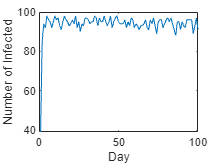

% Step 1. Set up Network Representation
N = 100;                                        % Number of individuals

% Random symmetric matrix
network = rand(N);
network = triu(network, 1);
network = network + network';

% Apply a threshold to make it a logical matrix
threshold = 0.5;
network = network > threshold;

% Initialize the state of individuals (0 = Susceptible, 1 = Infected)
state = zeros(N, 1);

% Randomly assign a few individuals as Infected
num_initially_infected = 5;
infected_indices = randperm(N, num_initially_infected);
state(infected_indices) = 1;

% Step 2. Simulate
% CUSTOMIZE PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_days = 100;                                 % days
infect_prob = 0.04;                             % infection prob (4% was given in paper)
recover_prob = 0.1;                             % recovery prob
num_infected = zeros(num_days, 1);              % Vector of infected individuals each day
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for day = 1:num_days                            % For each individual...
    for i = 1:N                                 % If the individual is infected...
        if state(i) == 1                       
            contacts = find(network(i, :));     % Find the individuals they are in contact with
            for j = contacts                    % For each contact...
                if state(j) == 0                % If the contact is susceptible...
                    if rand < infect_prob       % They become infected with infect_prob
                        state(j) = 1;
                    end
                end
            end
            if rand < recover_prob              % The infected individual recovers with a recover_prob
                state(i) = 0;
            end
        end
    end  
    % Record the number of infected individuals
    num_infected(day) = sum(state);
end

% Plot the number of infected individuals over time
figure;
plot(1:num_days, num_infected);
xlabel('Day');
ylabel('Number of Infected');